To begin, I loaded the provided population data into MATLAB (file was modified to have year and population data in two columns)

- y is a variable with all years and P is a variable storing population data (billions)

[y, P] = readvars("Pop_Data.txt","NumHeaderLines",1);

**a) Initial Data Plotting**

I plotted the population record on linear, semi-log, and log-log graphs

- **linear:**

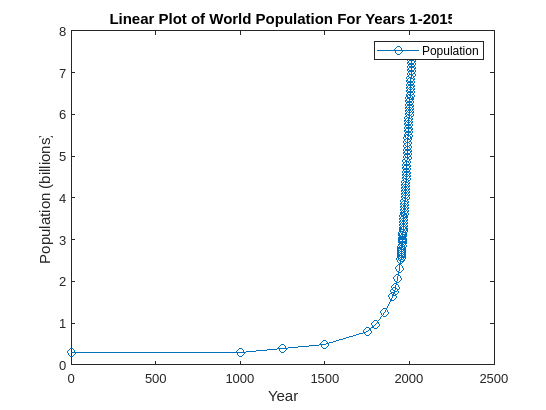

figure
plot(y,P,'o-')
title("Linear Plot of World Population For Years 1-2015")
ylabel("Population (billions)")
xlabel("Year")
legend("Population")

This plot shows world population (y axis) from the years 1 to 2015 (x axis).  It has the classic exponential growth shape, which shows that population began to increase rapidly beginning around the 17th to 19th centuries and continuing to today. 

- **semi-log:**

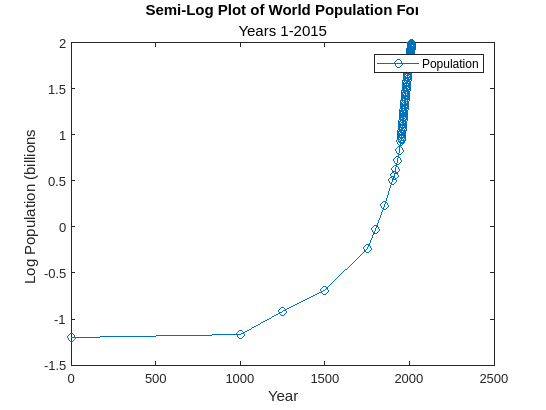

figure
plot(y,log(P),'o-')
title("Semi-Log Plot of World Population For", "Years 1-2015")
ylabel("Log Population (billions)")
xlabel("Year")
legend("Population")

The shape of this semi-log plot of the log of population (y axis) versus year (x axis) is the closest to a straight line of the three plots, however, the curvature of the line indicates that the world population is experiencing exponential growth and may be best represented using an exponential model.

- **log-log:**

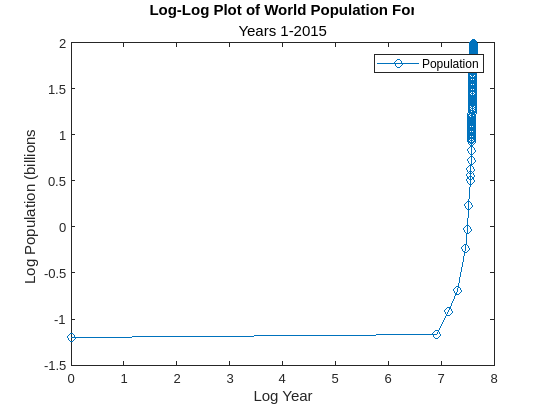

figure
plot(log(y),log(P),'o-')
title("Log-Log Plot of World Population For", "Years 1-2015")
ylabel("Log Population (billions)")
xlabel("Log Year")
legend("Population")

The shape of this log-log plot of the logarithms of population (y axis) and year (x-axis) is similar to the linear plot and is skewed to the right likely due to the lack of data in ancient times and the aforementioned population growth in more recent times.  This likely would not work well with a power law-based model.

**b) Exponential Function Plotting**

To fit the data using an exponential function, a MATLAB function file was created called "expofunc.m".  This function file contained the following two lines to compute the model function P(y), which is global population as a function of time and assumes a pre-existing population prior to exponential growth:

    function out=expofunc(x, a)

    out = a(1)*exp(a(2)*y);    

The provided "nleasqr.m" and "dfdp.m" files were used for nonlinear least squares fitting.

- All data before the year 1500 was removed due to poor model fitting.

[y, P] = readvars("Pop_Data_mod.txt","NumHeaderLines",1);

Initial Parameters:

- Based on the semi-log plot from part a, the beginning of exponential growth appeared to occur around the year 1800 at a log population of 0.0002 (a(1)), and the specific growth rate was estimated as 0.005 (a(2)).

- The equation is P = a1 + a2e^ut

ain = [0.0002 0.005];
[f,a,kvg,iter,corp,covp,covr,stdresid,Z,r2] = nlleasqr(y,P,ain,'expofunc');

 CONVERGENCE NOT ACHIEVED! 


Plotted intital guess models with the global population data:

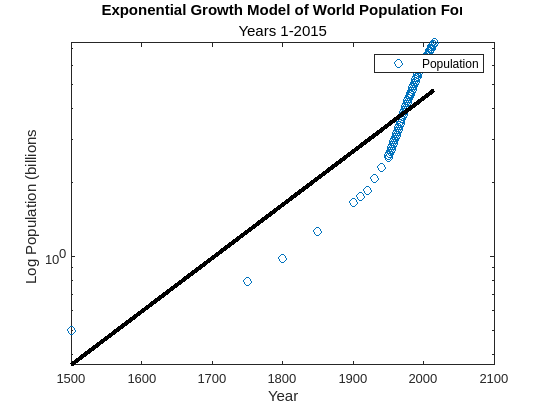

figure
semilogy(y,P,'o')
hold on
semilogy(y,expofunc(y,ain),'k','LineWidth',3)
title("Exponential Growth Model of World Population For", "Years 1-2015")
ylabel("Log Population (billions)")
xlabel("Year")
legend("Population")

Estimated coefficient of determination

coefficients = a'

coefficients =     0.0000    0.0094


sigmas = sqrt(diag(covp))'

sigmas = 1.0e-03 *

    0.0001    0.7877


R2 = r2

R2 = 0.9240

The line appears to fit decently well after removing outliers (data for years before 1500), however, the data is not linear.  The coefficient of determination was 0.9240.

**c) Power Law Fitting**

A function file called "powerfunc.m" was created to define the power law function:


$$\frac{\partial }{\partial t}P=a\left(t^b \right)$$


function out = powerfunc(y,a)

out = a(1)*y.^a(2);

In this case, P represents population (billions), t represents time (years), a is a constant, and b is the power law exponent.  Initial parameters were estimated as a1 = 0.25 and a2 = 1.

ain = [0.25 0.18];

Plotted semi-log plot with power law fitting based on initial parameter estimates:

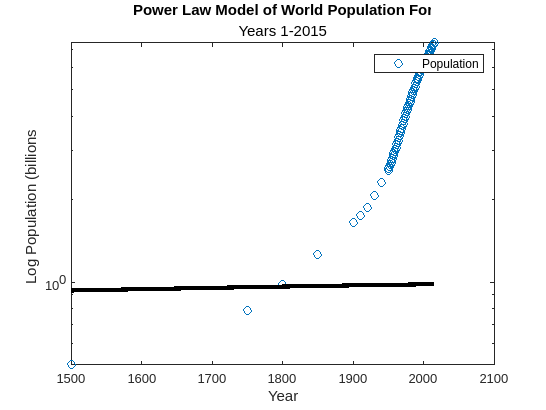

figure
semilogy(y,P,'o')
hold on
semilogy(y,powerfunc(y,ain),'k','LineWidth',3)
title("Power Law Model of World Population For", "Years 1-2015")
ylabel("Log Population (billions)")
xlabel("Year")
legend("Population")